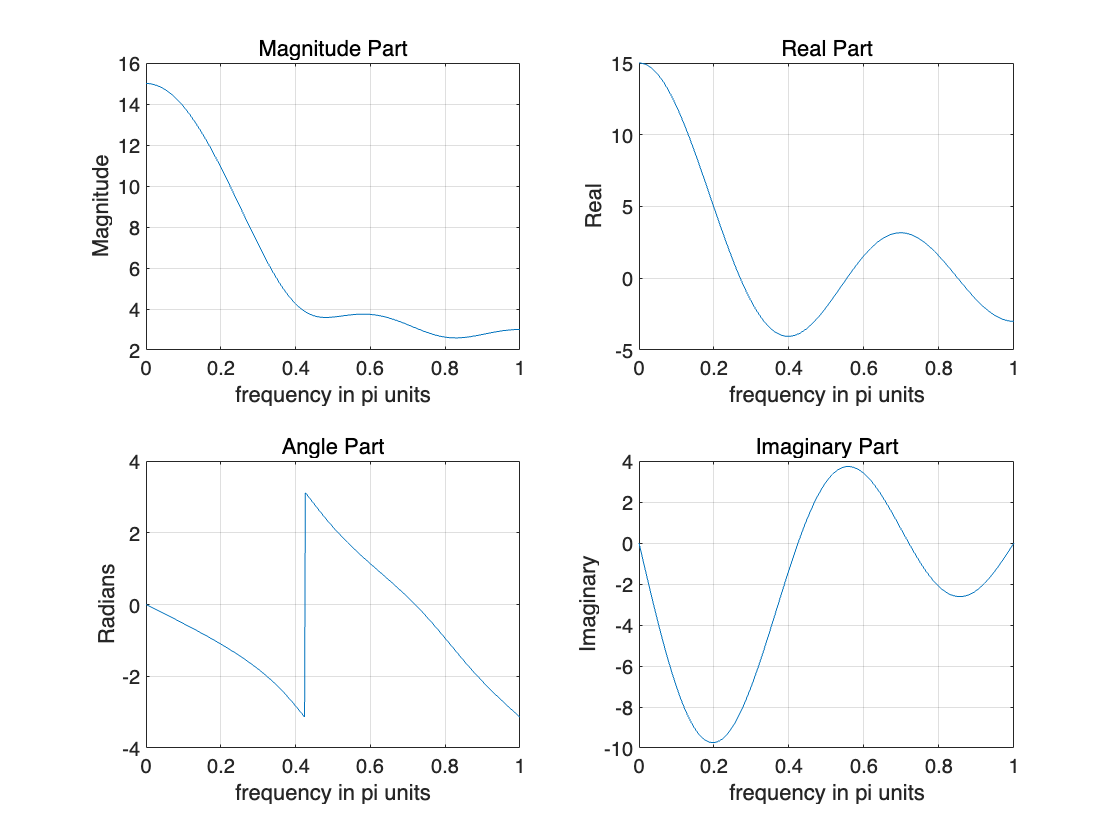

clc;
clear;
close;
clf;

n = -1:3;
x = 1:5;
k = 0:500;
w = linspace(0,pi,501);

X = x * (exp(-j*pi/500)) .^ (n'*k);

magX = abs(X); angX = angle(X);
realX = real(X); imagX = imag(X);

figure(7)
subplot(2,2,1); plot(w/pi,magX); grid on;
xlabel('frequency in pi units'); title('Magnitude Part'); ylabel('Magnitude')
subplot(2,2,3); plot(w/pi,angX); grid on;
xlabel('frequency in pi units'); title('Angle Part'); ylabel('Radians')
subplot(2,2,2); plot(w/pi,realX); grid on;
xlabel('frequency in pi units'); title('Real Part'); ylabel('Real')
subplot(2,2,4); plot(w/pi,imagX); grid on;
xlabel('frequency in pi units'); title('Imaginary Part'); ylabel('Imaginary')